#### 图像大小最好统一后，再进行标注工作。

标注采用Image Label进行，对图像文件进行标注处理。

## 1.1 导入数据

clear;clc;
load('gTruth.mat');    %把标注好的图像集导入

#### 1.1.2 读取图像位置

trainingfiles = gTruth.DataSource.Source;         %读图像
traininglabel = gTruth.LabelData;                 %读图像标签
imgfiles = imageDatastore(trainingfiles);
imglabel = boxLabelDatastore(traininglabel);
ds = combine(imgfiles, imglabel);                 %格式转换成可训练的格式，把各个图像和标签拼起来，让他们变成一个数据

## 1.2 可视化标记框

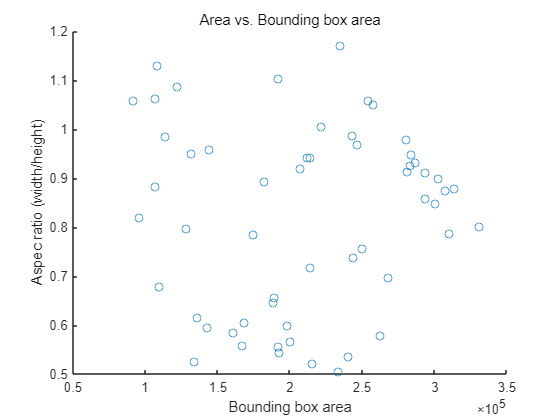

% 将所有图像整合
allBoxes = cell2mat(reshape(table2array(gTruth.LabelData),[],1));

% Plot bounding box area vs. aspect ratio
aspectRatio = allBoxes(:,3) ./ allBoxes(:,4);
area = prod(allBoxes(:,3:4),2);

figure
scatter(area,aspectRatio)
xlabel("Bounding box area")
ylabel("Aspec ratio (width/height)");
title("Area vs. Bounding box area")           %确定有多少个不同大小的框

## 1.3 确定框的数量

% Clustering into 4 groups
numAnchors = 2;

% Clustering data with K-Medoids
[clusterAssignments, anchorBoxes, sumd] = kmedoids(allBoxes(:,3:4),numAnchors,'Distance',@iouDistanceMetric);

% show the size of anchor boxes
disp(anchorBoxes);

   507   555
   319   528



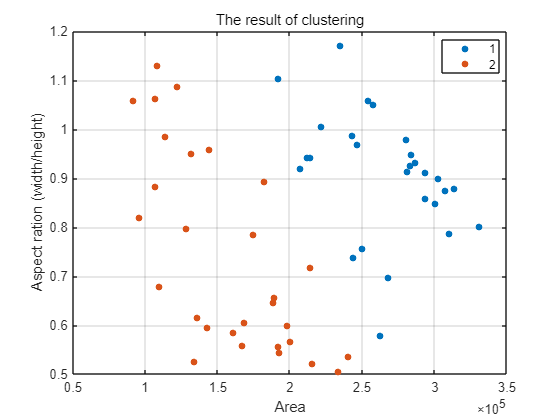


% plot the result of clustering
figure
gscatter(area,aspectRatio,clusterAssignments);
title("The result of clustering")
xlabel("Area")
ylabel("Aspect ration (width/height)");
grid


% Cumulative addition
counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);

%Calculate mean IoU
meanIoU = mean(1 - sumd./(counts));
disp("mean IoU : " + meanIoU);   %1.3整段预分类

mean IoU : 0.79935


## 1.4 确认anchor box数量与平均IoU的关系

Increasing the anchor box improves the average IoU but increases the computational complexity.

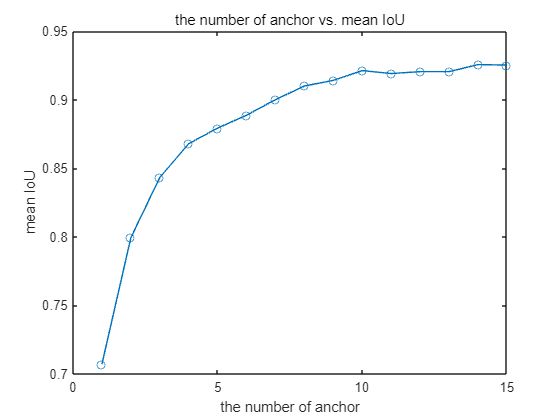


maxNumAnchors = 20;
for k = 1:maxNumAnchors
    
    % Clustering data with K-Medoids
    [clusterAssignments, ~, sumd] = kmedoids(allBoxes(:,3:4),k,'Distance',@iouDistanceMetric);
    
    % Calculate mean IoU
    counts = accumarray(clusterAssignments, ones(length(clusterAssignments),1),[],@(x)sum(x)-1);
    meanIoU(k) = mean(1 - sumd./(counts));
end

figure
plot(1:maxNumAnchors, meanIoU,'-o')
ylabel("mean IoU")
xlabel("the number of anchor")
title("the number of anchor vs. mean IoU")      %数据集在多少的时候对数据集学习分类准确度的预测

## 1.5 搭建Yolov2模型

network = alexnet();    % load pretrained model
featureLayer = 'pool5'; % Specify the layer to be used for feature extraction
imageSize =[224 224 3]; %输入图像大小，可调整（input image size）
% the number of classes
numClasses = width(gTruth.LabelData);
anchorBoxes(:,1) =anchorBoxes(:,1)*224/720;                                     %这里224对应调整后[224 224 3];410对应原始图像[720 1280 3]，数据归一化
anchorBoxes(:,2) =anchorBoxes(:,2)*224/1280;
% define yolo v2 detector
lgraph = yolov2Layers(imageSize, numClasses, round(anchorBoxes), ...
    network, featureLayer);    %把数据集和特征放到模型里
% visualize network
%analyzeNetwork(lgraph)
options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.001, ...
    'Verbose', true, 'MiniBatchSize', 16, 'MaxEpochs', 100,...
    'Shuffle', 'every-epoch', 'VerboseFrequency', 10);                           %训练策略，用什么样的方法去训练，根据数据集来设置的，也有其他的训练方式，根据数据集和其他开源项目的一些代码中的对比得出来的比较合适的参数

## 1.6 训练Yolo v2模型

doTraining = true;%把这里改为true即可训练 false关闭模型
if doTraining
    rng('default');
    tic;
    [detector,info] = trainYOLOv2ObjectDetector(ds,lgraph,options);
    toc
    save('trainedYOLOv2Detector','detector','info');
else
    load('trainedYOLOv2Detector');
end

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* normal
* drowning

在单 GPU 上训练。
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　小批量损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　　　　　１．６０　｜　　　　　２．６　｜　　０．００１０　｜
｜　　１０　｜　　　１０　｜　　　　　００：００：１５　｜　　　　　　　０．８０　｜　　　　　０．６　｜　　０．００１０　｜
｜　　２０　｜　　　２０　｜　　　　　００：００：２９　｜　　　　　　　０．４９　｜　　　　　０．２　｜　　０．００１０　｜
｜　　３０　｜　　　３０　｜　　　　　００：００：４４　｜　　　　　　　０．４３　｜　　　　　０．２　｜　　０．００１０　｜
｜　　４０　｜　　　４０　｜　　　　　００：００：５９　｜　　　　　　　０．３４　｜　　　　　０．１　｜　　０．００１０　｜
｜　　５０　｜　　　５０　｜　　　　　００：０１：１３　｜　　　　　　　０．２８　｜　７．６ｅ－０２　｜　　０．００１０　｜
｜　　６０　｜　　　６０　｜　　　　　００：０１：２７　｜　　　　　　　０．２９　｜　８．２ｅ－０２　｜　　０．００１０　｜
｜　　７０　｜　　　７０　｜　　　　　００：０１：４２　｜　　　　　　　０．２６　｜　６．９ｅ－０２　｜　　０．００１０　｜
｜　　８０　｜　　　８０　｜　　　　　００：０１：５６　｜　　　　　　　０．２７　｜　７．４ｅ－０２　｜　

历时 184.592918 秒。


## 1.7 使用训练好的模型测试

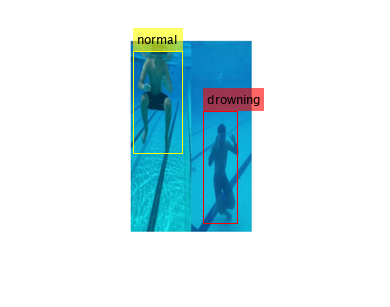

% 读取一张图像
n = randi(28) ;%随机选取一张图像识别
I = imresize(imread(cell2mat(gTruth.DataSource.Source(n))),[224 224]);
% 使用模型检测
[bboxes, scores, labels] = detect(detector, I);
% Colormap index generation for labels
[~,ind] = ismember(labels,gTruth.LabelDefinitions.Name);
% 展示结果
% 定义框颜色 = 分类数量
cmaps = [
    255 255 000;         %黄色
    255 000 000          %红色
    ];
if ~isempty(labels)
    detectedImg = insertObjectAnnotation(I, 'Rectangle', bboxes, cellstr(labels),...
    'Color',cmaps(ind,:));
    figure
    imshow(detectedImg)
else
    imshow(I)
    title("未识别到目标物")
end

## 支持函数

function dist = iouDistanceMetric(boxWidthHeight,allBoxWidthHeight)
% Calculate metric as distance based on IoU

% add x, y to caluculate IoU as bounding box
boxWidthHeight = prefixXYCoordinates(boxWidthHeight);
allBoxWidthHeight = prefixXYCoordinates(allBoxWidthHeight);

% Convert IoU to distance
dist = 1 - bboxOverlapRatio(allBoxWidthHeight, boxWidthHeight);
end

function boxWidthHeight = prefixXYCoordinates(boxWidthHeight)
% add x, y to caluculate IoU as bounding box
n = size(boxWidthHeight,1);
boxWidthHeight = [ones(n,2) boxWidthHeight];
end                                        %为分类部分提供的函数，自带的